# Homework 5

## Problem Formulation

% Initial Conditions
x0 = [0;0;0;0;0;0];

% Refernece
ref = [5; 0; 0; 0; 0; 0];

% Prediction Horizon
N = 30;

% Sampling Time
dt = 0.04;

% Number of Constraints
cn = 8;

## Part A and B:

for i = 1:2
[n,m] = Hw5_Initialize(dt,ref,0,i);

Then, given an initial guess $\left(z^0 ,\lambda^0 \right)$

% Initial guess
z = zeros((n+m)*N,1);
l = zeros( n   *N,1); 

## NMPC Implementation without Constraints

% Solver Settings
imax = 4;
tol = 1e-2;

% Receding Horizon NMPC
T = 4;

xtt = zeros(n,T/dt);
ytt = zeros(1,T/dt);
utt = zeros(m,T/dt);
x = x0;
for tt = 1:T/dt
    
    % Solve NLP
    for iter = 1:imax
        
        % Generate sub-QP
        [H,h,E,e,C,c] = gen_QP(z,l,x,n,m,N,cn);
    
        % Solve sub-QP
        [dz,l] = solve_QP(H,h,E,e,C,c,0);
        
        % Update solution estimate
        z = z + dz;
        
        % Check residual
        % res = [H*z+E'*l ; e ]'*[H*z+E'*l ; e ];
        res = dz'*dz;
    
        if res <= tol
            % NLP Solved!
            break
        end
    
    end
    
    % Control Input
    u = z(1:m);
    
    % Save Data
    utt(:,tt) = u;
    xtt(:,tt) = x;
    ytt(:,tt) = x(5)-atan((x(2)+1.56*x(4))/30);
    
    % Update System
    x = f(x,u);

end

We now plot the trajectory of the closed-loop system subject to a receding horizon NMPC (bue) with no terminal cost, as well as the NMPC (red) with terminal cost  

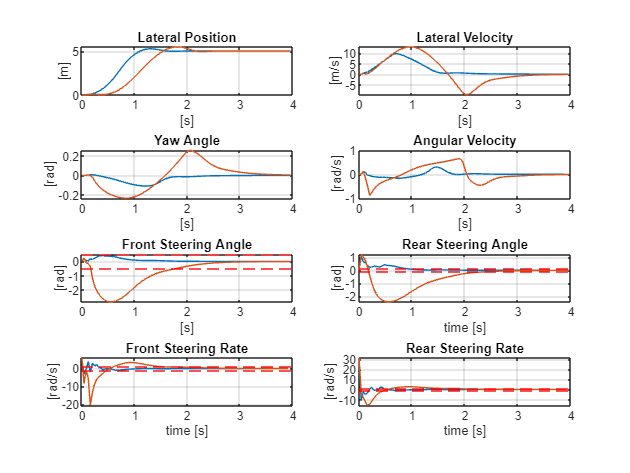

sys_plot(0:dt:T-dt,xtt,utt(:,1:end-1));
end

The blue line shows NMPC without terminal cost and constraints, and the red line depicts NMPC with terminal cost but no constraints. Both controllers breach constraints, but the NMPC with terminal cost appears smoother, which is advantageous for actual systems. However, the sharp decrease and increase in angular velocity before the first second are concerning and undesirable. The red line, representing the NMPC with terminal cost, shows smoother and more consistent control actions, especially in terms of steering angles and rates. Additionally, incorporating terminal cost helps keep steering rates within safer ranges, indicating a less aggressive and more predictive approach to control. This strategy is likely to reduce mechanical wear and improve safety.

## Part C:

## NMPC Implementation with Constraints

We now implement constraints on steering angles

% Initial guess
z = zeros((n+m)*N,1);
l = zeros( n   *N,1); 

% Solver Settings
imax = 4;
tol = 1e-2;

% Receding Horizon NMPC
T = 4;

xtt = zeros(n,T/dt);
ytt = zeros(1,T/dt);
ytt1 = zeros(1,T/dt);
utt = zeros(m,T/dt);
x = x0;
for tt = 1:T/dt
    
    % Solve NLP
    for iter = 1:imax
        
        % Generate sub-QP
        [H,h,E,e,C,c] = gen_QP(z,l,x,n,m,N,cn);
    
        % Solve sub-QP
        [dz,l] = solve_QP(H,h,E,e,C,c,1);
        
        % Update solution estimate
        z = z + dz;
        
        % Check residual
        % res = [H*z+E'*l ; e ]'*[H*z+E'*l ; e ];
        res = dz'*dz;
    
        if res <= tol
            % NLP Solved!
            break
        end
    
    end
    
    % Control Input
    u = z(1:m);
    
    % Save Data
    utt(:,tt) = u;
    xtt(:,tt) = x;
    ytt(:,tt) = x(5)-atan((x(2)+1.56*x(4))/30);
    ytt1(:,tt) = x(6)-atan((x(2)-1.64*x(4))/30);
    
    % Update System
    x = f(x,u);

end

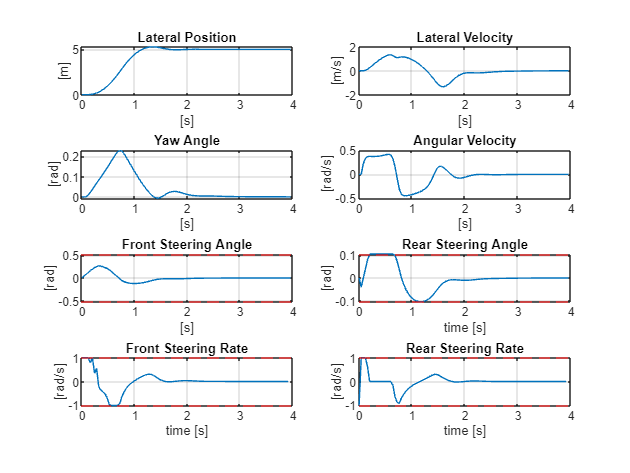

figure
sys_plot(0:dt:T-dt,xtt,utt(:,1:end-1));

The above results indicate that the system effectively maintains constraints even without implementing terminal constraints, likely because of a sufficiently extended prediction horizon. If the prediction horizon were shorter, the system might fail to achieve the reference values or could breach the constraints. Specifically, the lateral position and steering rates are well-controlled throughout the test period, suggesting stable and predictive control behavior across the observed parameters.

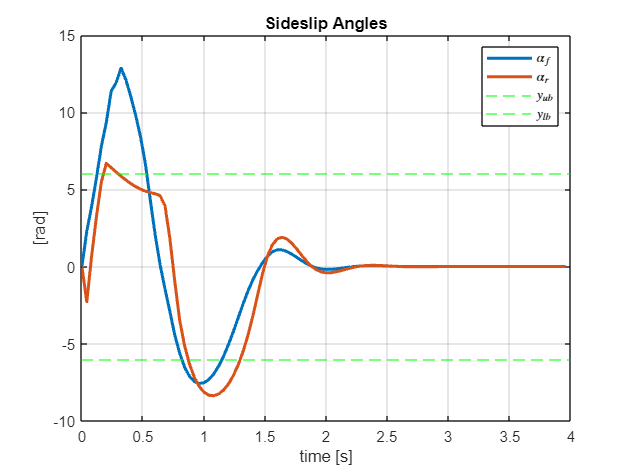

figure
plot(0:dt:T-dt,rad2deg(ytt),'LineWidth', 2); hold on; grid on
plot(0:dt:T-dt,rad2deg(ytt1),'LineWidth', 2);
yline(6,'--g')
yline(-6,'--g')
ylabel('[rad]')
xlabel('time [s]')
title('Sideslip Angles')
legend('$\alpha_f$','$\alpha_r$','$y_{ub}$','$y_{lb}$','Interpreter','latex')

The graph displays the side slip angles over time, where it's evident that the constraints (marked by the green dashed lines) are not adhered to. Specifically, both curves exceed these predefined limits, particularly notable around the 0.5 second mark where the blue curve spikes sharply beyond the upper constraint before dropping below the lower constraint. This suggests a breach in maintaining the required side slip angle limits.

## Part D:

## NMPC Implementation with Constraints on sideslip angles

We now introduce constraints on side slip angles $\alpha_f$ and $\alpha_r$.

cn = 12;

[n,m] = Hw5_Initialize(dt,ref,1,2);

% Initial guess
z = zeros((n+m)*N,1);
l = zeros( n   *N,1); 

% Solver Settings
imax = 4;
tol = 1e-2;

% Receding Horizon NMPC
T = 4;

xtt = zeros(n,T/dt);
ytt = zeros(1,T/dt);
ytt1 = zeros(1,T/dt);
utt = zeros(m,T/dt);
x = x0;
for tt = 1:T/dt
    
    % Solve NLP
    for iter = 1:imax
        
        % Generate sub-QP
        [H,h,E,e,C,c] = gen_QP(z,l,x,n,m,N,cn);
    
        % Solve sub-QP
        [dz,l] = solve_QP(H,h,E,e,C,c,1);
        
        % Update solution estimate
        z = z + dz;
        
        % Check residual
        % res = [H*z+E'*l ; e ]'*[H*z+E'*l ; e ];
        res = dz'*dz;
    
        if res <= tol
            % NLP Solved!
            break
        end
    
    end
    
    % Control Input
    u = z(1:m);
    
    % Save Data
    utt(:,tt)  = u;
    xtt(:,tt)  = x;
    ytt(:,tt)  = x(5)-atan((x(2)+1.56*x(4))/30);
    ytt1(:,tt) = x(6)-atan((x(2)-1.64*x(4))/30);
    
    % Update System
    x = f(x,u);

end

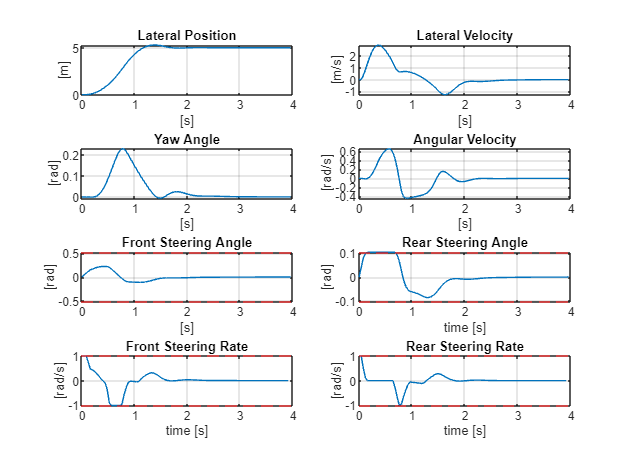

figure
sys_plot(0:dt:T-dt,xtt,utt(:,1:end-1))

The plots illustrate that side slip constraints have been effectively implemented, with the system maintaining smooth and stable control within the established limits throughout the duration. None of the parameters, including lateral position, velocity, and steering angles, show any breaches of the defined constraints, indicating robust control and adherence to the operational parameters set.

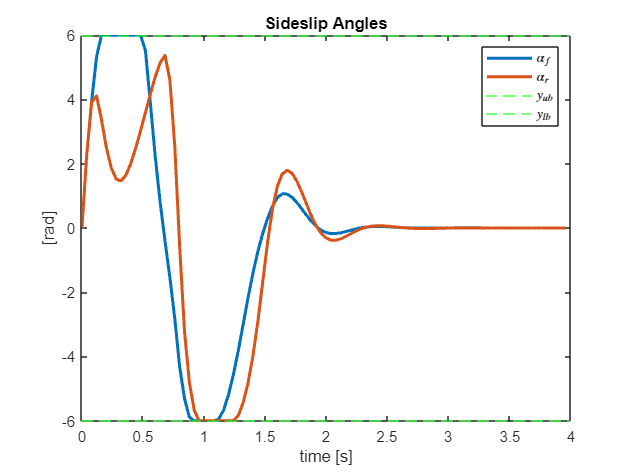

figure
plot(0:dt:T-dt,rad2deg(ytt),'LineWidth', 2); hold on
plot(0:dt:T-dt,rad2deg(ytt1),'LineWidth', 2);
yline(6,'--g')
yline(-6,'--g')
ylabel('[rad]')
xlabel('time [s]')
title('Sideslip Angles')
legend('$\alpha_f$','$\alpha_r$','$y_{ub}$','$y_{lb}$','Interpreter','latex')

The plot shows the side slip angles over time with two lines representing different angles. The data suggests that the side slip angle constraints are being effectively enforced across both. The initial fluctuations, where both lines peak sharply and then stabilize, indicate momentary exceedances, but the angles quickly return to within acceptable boundaries, maintaining constraint adherence for the majority of the duration.

# Auxiliary Functions

function sys_plot(t,X,U)
% Create one figure with eight subplots
subplot(4,2,1)
plot(t,X(1,:))
ylabel('[m]')
xlabel('[s]')
title('Lateral Position')
grid on
hold on

subplot(4,2,2)
plot(t,X(2,:))
ylabel('[m/s]')
xlabel('[s]')
title('Lateral Velocity')
grid on
hold on

subplot(4,2,3)
plot(t,X(3,:))
ylabel('[rad]')
xlabel('[s]')
title('Yaw Angle')
grid on
hold on

subplot(4,2,4)
plot(t,X(4,:))
ylabel('[rad/s]')
xlabel('[s]')
title('Angular Velocity')
grid on
hold on

subplot(4,2,5)
plot(t,X(5,:))
ylabel('[rad]')
xlabel('[s]')
title('Front Steering Angle')
yline(deg2rad(30),'--r')
yline(deg2rad(-30),'--r')
grid on
hold on

subplot(4,2,6)
plot(t,X(6,:))
ylabel('[rad]')
xlabel('time [s]')
title('Rear Steering Angle')
yline(deg2rad(6),'--r')
yline(deg2rad(-6),'--r')
grid on
hold on

% figure
subplot(4,2,7)
plot(t(1:end-1),U(1,:))
ylabel('[rad/s]')
xlabel('time [s]')
title('Front Steering Rate')
yline(1,'--r')
yline(-1,'--r')
grid on
hold on

subplot(4,2,8)
plot(t(1:end-1),U(2,:))
ylabel('[rad/s]')
xlabel('time [s]')
title('Rear Steering Rate')
yline(1,'--r')
yline(-1,'--r')
grid on
hold on
end